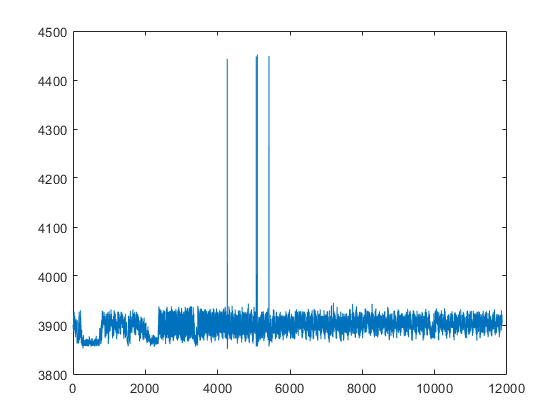

%Define Sample Frequency
Fs=1060;
%Define Recording Length (seconds)
L=length(CTvoltage)/1060;

y=CTvoltage(1:end-2,1);

%Plot Data
plot(y);

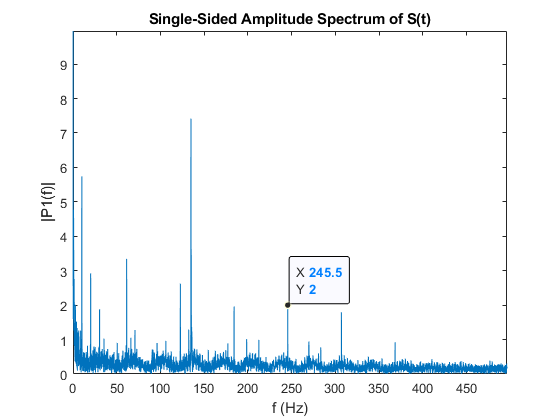

%Perform FFT Analysis
%Calculate time values
tt=linspace(0,L,length(y));

%Compute FFT
Y=fft(y);
L=Fs*L;

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

%Define frequency domain and plot
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')